clc; clear ; close all
import robo.*

theta90 = deg2rad(90)

theta90 = 1.5708

Rz = [cos(theta90) -sin(theta90) 0;
    sin(theta90) cos(theta90) 0;
    0 0 1]

Rz =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


Ry = [cos(-theta90) 0 sin(-theta90);
    0 1 0;
    -sin(-theta90) 0 cos(-theta90)]

Ry =     0.0000         0   -1.0000
         0    1.0000         0
    1.0000         0    0.0000


p0 = [0;5; 0] %spatial frame coordinate 

p0 =      0
     5
     0


p1 = [-5;0;5]

p1 =     -5
     0
     5


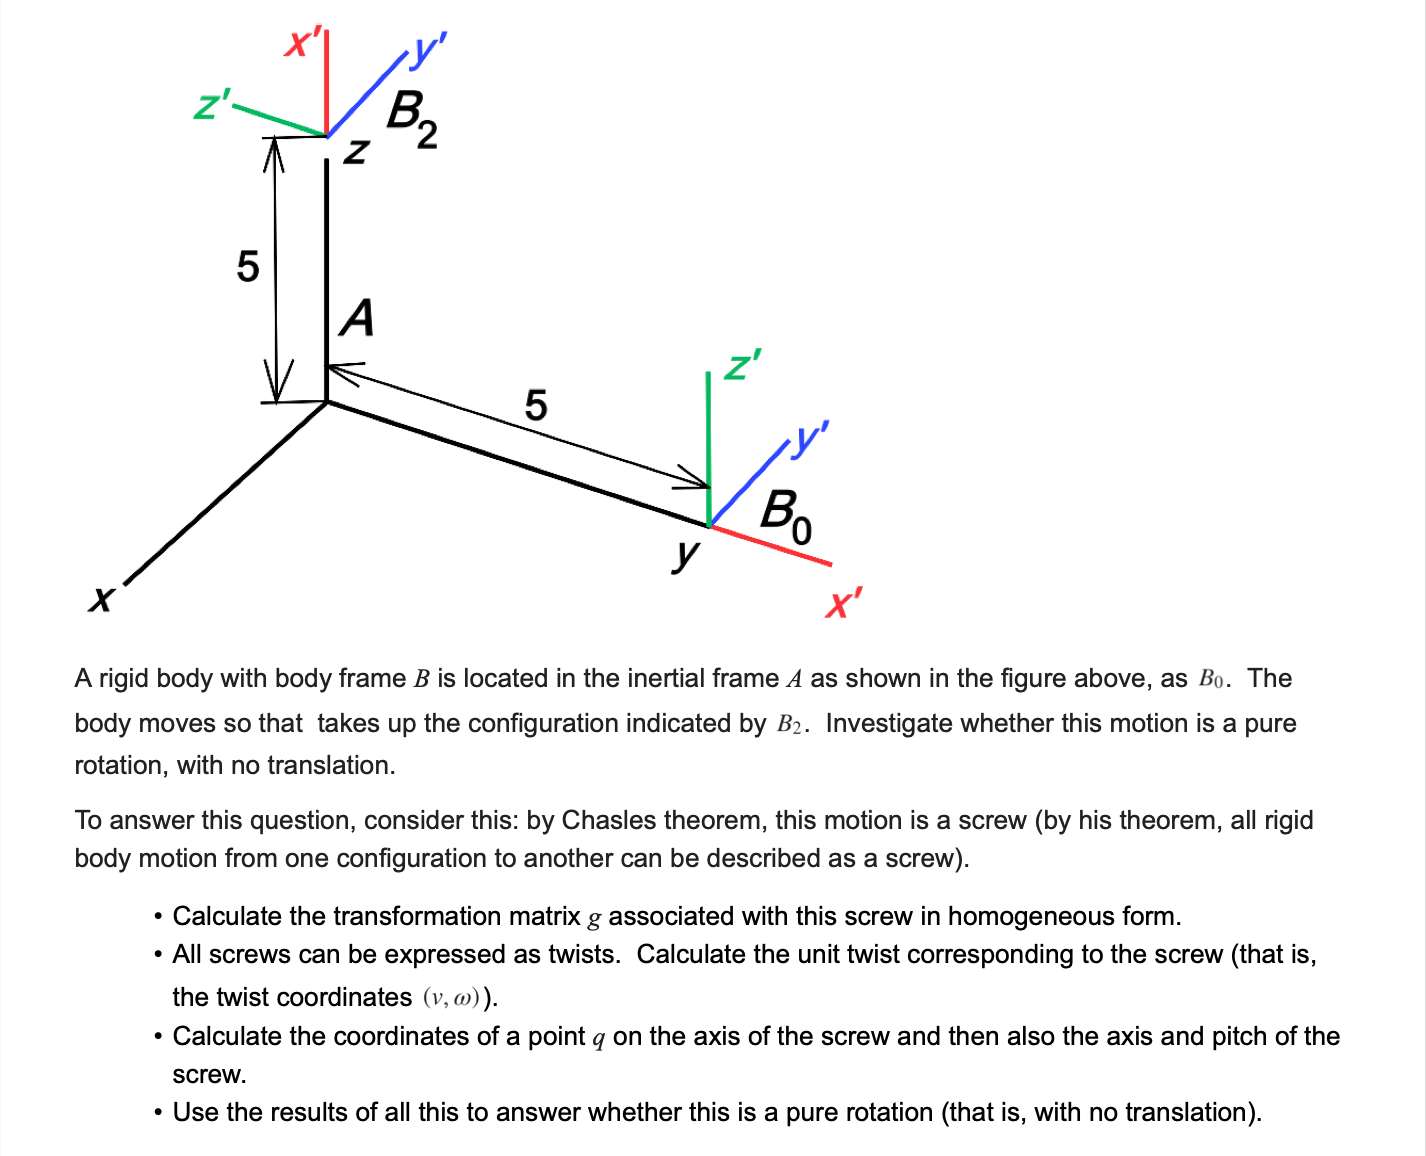

T0 = gmat(Rz,p0)

T0 =     0.0000   -1.0000         0         0
    1.0000    0.0000         0    5.0000
         0         0    1.0000         0
         0         0         0    1.0000


T1 = gmat(Ry,p1)

T1 =     0.0000         0   -1.0000   -5.0000
         0    1.0000         0         0
    1.0000         0    0.0000    5.0000
         0         0         0    1.0000


T01 = T0 * T1 %spatial trans matrix

T01 =     0.0000   -1.0000   -0.0000   -0.0000
    0.0000    0.0000   -1.0000         0
    1.0000         0    0.0000    5.0000
         0         0         0    1.0000



%calc spatial opeartor
G01 = T01/T0 % T01 * T0^-1 = T01 / T0

G01 =     1.0000   -0.0000   -0.0000         0
   -0.0000    0.0000   -1.0000   -0.0000
    0.0000    1.0000    0.0000    0.0000
         0         0         0    1.0000



%提取rot matrix

rotm = G01(1:3, 1:3);

axang = rotm2axang(rotm)

axang =     1.0000   -0.0000         0    1.5708



omega = axang(1:3)' %tmd 一定要注意弄成column啊

omega =     1.0000
   -0.0000
         0


theta = axang(4)

theta = 1.5708


omega_h = hatm(omega)

omega_h =          0         0   -0.0000
         0         0   -1.0000
    0.0000    1.0000         0


A = ((eye(3) - rodrigues(omega,theta))*omega_h + omega*omega'*theta)

A =     1.5708   -0.0000   -0.0000
   -0.0000    1.0000   -1.0000
    0.0000    1.0000    1.0000


p = G01(1:3 , 4);%终极spatial坐标
% A * v = p


v = A\p % A^-1 * p

v = 1.0e-15 *

    0.0000
   -0.1531
    0.1531



xi = [v;omega]

xi =     0.0000
   -0.0000
    0.0000
    1.0000
   -0.0000
         0



h_xi = [omega_h,v;zeros(1,3),0]

h_xi =          0         0   -0.0000    0.0000
         0         0   -1.0000   -0.0000
    0.0000    1.0000         0    0.0000
         0         0         0         0


xi_h = wedge(xi)

xi_h =          0         0   -0.0000    0.0000
         0         0   -1.0000   -0.0000
    0.0000    1.0000         0    0.0000
         0         0         0         0


exp_xi = exp_se3(xi,theta)

exp_xi =     1.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -1.0000   -0.0000
    0.0000    1.0000    0.0000         0
         0         0         0    1.0000


shouldbezero1  = xi_h - h_xi

shouldbezero1 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
